# Trabalho Computacional

Considere uma planta contendo um motor de corrente contínua (MCC) que aciona uma determinada carga. Deseja-se controlar a velocidade do eixo do motor em função da tensão terminal aplicada a seus terminais. Sabe-se que sua modelagem física conduz ao seguinte sistema de equações:


$$\begin{cases} V_t(t) = L_a \frac{di_a(t)}{dt} + R_ai_a(t) + E_a(t) \\
                       E_a(t) = K_e\omega(t) \\
                       \omega(t) = \frac{d\theta(t)}{dt} \\
                       \tau_\text{ele} - \tau_L(t) = J\frac{d\omega(t)}{dt} + b\omega(t) \\
                       \tau_\text{ele} = K_\tau i_a(t) \\
                       \tau_L(t) = J_L \frac{\omega(t)}{dt} + b_L \omega(t)
 \end{cases}$$


sendo:

## Seção 0: Análise do Sistema

### 1. Diagrama de blocos do sistema

Aplicando a transformada de Laplace no sistema de equações dado considerando condições iniciais nulas se segue que:


$$\begin{cases} V_t(s)- E_a(s)  = (L_as + R_a)I_a(s)\\
                       E_a(s) = K_e\omega(s) \\
                       \tau_\text{ele}(s) - \tau_L(s) = (Js+b)\omega(s) \\
                       \tau_\text{ele}(s) = K_\tau I_a(s) \\
                       \tau_L(s) = (J_Ls+ b_L) \omega(s)
 \end{cases}$$


A partir destas equações é possível montar o diagrama de blocos completo do sistema como é apresentado abaixo. Perceba que se o distúrbio $T_L$ for exatamente como descrita na última equação, é possível fazer uma simplificação da malha no qual se resulta:


$$\frac{\omega(s)}{\tau_\text{ele}(s)} = \frac{\frac{1}{Js+B}}{1 + \frac{J_Ls + B_L}{Js+B}}=\frac{1}{(J+J_L)s + B+B_L}$$


[image: DB.svg]

### 2. Funções de transferência

Adaptando o diagrama de blocos para que o distúrbio $\tau_L$ seja uma entrada segue

[image: DB_c.svg]

A função de transferência de $\omega(s)$ em relação a $V_t(s)$ é obtida considerando $\tau_L(s)=0$ e então:


$$\frac{\omega(s)}{V_t(s)}=\frac{\frac{1}{L_as+R_a} \cdot K_\tau \cdot \frac{1}{J_{eq}s+B_{eq}}}{1+\frac{1}{L_as+R_a} \cdot K_\tau \cdot \frac{1}{J_{eq}s+B_{eq}} \cdot K_e} = \frac{K_\tau}{(L_as+R_a)(J_{eq}s+B_{eq}) + K_\tau K_e}$$


simplificando,


$$\frac{\omega(s)}{V_t(s)}=\frac{K_\tau}{L_aJ_{eq}s^2+(L_aB_{eq}+R_aJ_{eq})s+R_aB_{eq}+ K_\tau K_e}$$


A função de transferência de $\omega(s)$ em relação a $\tau_L(s)$ é obtida considerando $V_t(s)=0$ e então:


$$\frac{\omega(s)}{\tau_L(s)}=\frac{- \frac{1}{J_{eq}s+B_{eq}}}{1+\frac{1}{L_as+R_a} \cdot K_\tau \cdot \frac{1}{J_{eq}s+B_{eq}} \cdot K_e} = -\frac{L_as + R_a}{(L_as+R_a)(J_{eq}s+B_{eq}) + K_\tau K_e}$$


simplificando


$$\frac{\omega(s)}{\tau_L(s)}=-\frac{L_as+R_a}{L_aJ_{eq}s^2+(L_aB_{eq}+R_aJ_{eq})s+R_aB_{eq}+ K_\tau K_e}$$


### 3. Resposta ao degrau

Definindo os parâmetros

La = 2.3;       % H
Ra = 0.9;       % Ohm
J  = 2.3e-3;    % kg.m²
b  = 5.29e-3;   % N.m.s/rad
Jl = 0.0479958; % kg.m²
bl = 0.0529;    % N.m.s/rad
Ke = 0.011446;  % V.s/rad
Kt = 0.3913;    % N.m/A
Jeq = J+Jl;
Beq = b+bl;

Definindo as funções de transferência

G  = tf(Kt,[La*Jeq, La*Beq+Ra*Jeq, Ra*Beq+Kt*Ke])       % w(s)/Vt(s)


G =
 
              0.3913
  -------------------------------
  0.1157 s^2 + 0.1791 s + 0.05685
 
Continuous-time transfer function.
Model Properties


Gd = tf(-[La,Ra],[La*Jeq, La*Beq+Ra*Jeq, Ra*Beq+Kt*Ke]) % w(s)/Tl(s)


Gd =
 
           -2.3 s - 0.9
  -------------------------------
  0.1157 s^2 + 0.1791 s + 0.05685
 
Continuous-time transfer function.
Model Properties


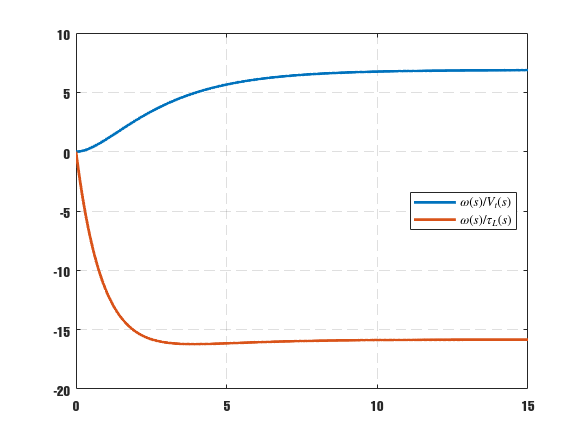

figure;
t=linspace(0,15,1001);
% aplicada entrada degrau nas duas FT
y = step(G,t); yd = step(Gd,t);
plot(t,y, 'LineWidth',2); hold on;
plot(t,yd,'LineWidth',2);
% config. plot
xlim([0,15]); grid on; set(gca,'GridLineStyle','--')
legend({'$\omega(s)/V_t(s)$','$\omega(s)/\tau_L(s)$'},...
    'Interpreter','latex','Location','east');

### 4. Análise

O conjunto do motor de corrente contínua (MCC) e a carga são modelados a partir das equações diferenciais obtidas a partir do conhecimento físico da planta. Para facilitar a obtenção das funções de transferência, o sistema de equações foi transformado no diagrama de blocos no qual se observa que a tensão de armadura $V_t(t)$ é uma entrada e a saída desejada é a velocidade de rotação $\omega(t)$. Adicionalmente existe uma segunda entrada exógena, o distúrbio $\tau_L(t)$. 

Com base no diagrama de blocos foram determinadas as funções de transferência $G(s)=\omega(s)/V_t(s)$ e $G_d(s)=\omega(s)/\tau_L(s)$. O denominador destas duas funções de transferência é idêntico, mudando somente o numerador. Enquanto o numerador de $G(s)$ é apenas um ganho $K_\tau$, $G_d(s)$ contém um zero em $s=-R_a/L_a$. Além disto o ganho da função de transferência do distúrbio é negativa pois um torque externo reduz a potência do motor, levando a uma diminuição de $\omega(t)$.

Os polos de $G(s)$ e $G_d(s)$ são $s=-1.1025$ e $s=-0.4457$. Portanto os sistemas são estáveis com um comportamento de resposta ao degrau superamortecido, isto é, sem a presença de sobressinal. Os ganhos estacionários são, respectivamente, $K_G=6.883$ e $K_{G_d}=-15.8312$. Observe que o valor de regime permanente de $\omega(t)$ é bem mais sensível ao distúrbio $\tau_L(t)$ do que a tensão de armadura $V_t(t)$. Além disto, $G_d(s)$ tem um zero em  $s=-0.3913$. 

Este resultado é comprovado pela simulação da resposta ao degrau unitário apresentada na figura acima. A amplitude da variação para a saída de $G_d(s)$ é mais de duas vezes maior do que a de $G(s)$. Além disto, como o distúrbio reduz a velocidade de rotação é preciso garantir que a tensão de entrada seja pelo menos 3 vezes maior do que a amplitude do distúrbio a fim de que o eixo do motor não fique parado. 

## Seção 3: Representação em Espaço de Estados

### 1. Representação em espaço de estados

Reescrevendo o sistema de equações:


$$\begin{cases} L_a \frac{di_a}{dt} = V_t(t) - E_a(t) - R_ai_a(t) = V_t(t) - K_e\omega(t) - R_ai_a(t) \\ 
J\frac{d\omega(t)}{dt}=\tau_\text{ele}(t)-\tau_L(t)-b\omega(t)=K_\tau i_a(t) - J_L\frac{d\omega(t)}{dt} - b_L\omega(t)-b\omega(t)
\end{cases}$$


Definindo os estados como sendo $x_1= i_a(t)$ e $x_2=\omega(t)$ e a entrada como sendo $u=V_t(t)$, pode-se reescrever as equações como sendo


$$\dot{x}_1 = \frac{1}{L_a} \left(  u - R_a x_1  - K_e x_2 \right)$$



$$\dot{x}_2= \frac{1}{J+J_L} \left[  K_\tau x_1 - (b+b_L)x_2  \right]$$


A representação em espaço de estados é

$\dot{x}(t) = Ax(t) + Bu(t)$        e        $y=Cx(t)$

no qual

[image: q3.svg]

e $J_{eq}=J+J_L$ e $b_{eq}=b+b_L$.

% matrizes
A = [-Ra/La, -Ke/La; Kt/Jeq, -Beq/Jeq];
B = [1/La; 0];
C = [0, 1];
% sistema em espaço de estados
sys = ss(A,B,C,0)


sys =
 
  A = 
              x1         x2
   x1    -0.3913  -0.004977
   x2       7.78     -1.157
 
  B = 
           u1
   x1  0.4348
   x2       0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


% polos
pol = pole(sys)

pol =    -0.4457
   -1.1025


% zeros
zer = zero(sys)


zer =

  0x1 empty double column vector



Os polos desta representação são os mesmos das representações em função de transferência, portanto houve consistência na modelagem em espaço de estados realizada. Além disto, não há zeros como não há zeros em $G(s)$. Portanto a representação em espaço de estados é idêntica a representação no domínio $s$ e o sistema mantém as mesmas características: estável com comportamento superamortecido.

### 3. Análise da controlabilidade e observabilidade

A matriz de controlabilidade é calculada por

[image: Mc.svg]

logo

Mc = [B, A*B] % matriz de controlabilidade

Mc =     0.4348   -0.1701
         0    3.3826


Se o posto da matriz for completo, seu determinante é não nulo. Verificando

dMc = det(Mc) % diferente de 0

dMc = 1.4707

Como $\det M_c = 1.4707 \neq 0$, $M_c$ tem posto completo e portanto o sistema tem estados completamente controláveis.

A matriz de observabilidade é calculada por

[image: Mo.svg]

logo

Mo = [C; C*A]  % matriz de observabilidade

Mo =          0    1.0000
    7.7800   -1.1570


Se o posto da matriz for completo, seu determinante é não nulo. Verificando

dMo = det(Mo)  % diferente de 0

dMo = -7.7800

Como $\det M_o = -7.78  \neq 0$, $M_o
$ tem posto completo e portanto o sistema tem estados completamente observáveis.

### 4. Controlador por realimentação de estados

Propondo um controlador da forma $u = -Kx(t) + r(t)$, sendo $r(t)$ um sinal de referência. A equação de espaço de estados se torna


$$\dot{x}=Ax+B(-Kx + r(t)) = (A-BK)x(t) + Br(t)$$


Perceba que na malha fechada, a matriz de estados é $A_{mf} = A-BK$. O objetivo é escolher $K$ de modo que $A_{mf}$ apresente os polos desejados. 

A localização dos polos desejados será 

$\mu_1=-2.5$     e     $\mu_2=-2.5$

ou seja, a malha fechada apresentará um comportamento criticamente amortecido com o tempo de acomodação pelo menos duas vezes menor do que a malha aberta. A equação característica é


$$\alpha(s) = (s+2.5)^2= s^2 + 5s + 6.25$$


Trocando $s$ por $A$ segue


$$\alpha(A) = A^2 + 5A + 6.25I$$


alf = A^2 + 5*A + 6.25*eye(2)

alf =     4.4079   -0.0172
   26.8544    1.7651


Aplicando a fórmula de Ackermann para calcular os ganhos $K$ segue


$$K=\left[ 0 \quad 1 \right] M_c^{-1} \alpha(A)$$


K = [0,1]/Mc*alf

K =     7.9390    0.5218


Realizando este controlador,

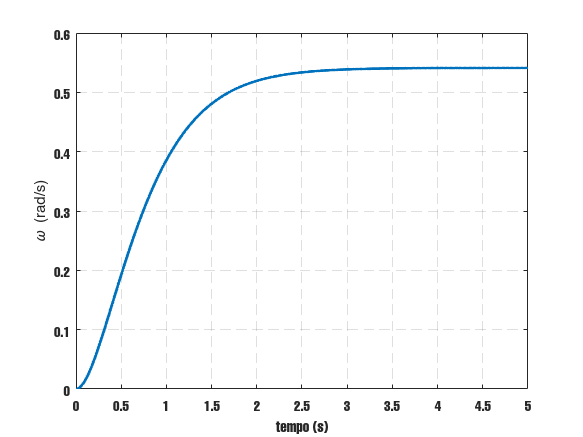

sys_mf = ss(A-B*K, B, C, 0); % malha fechada
% simula a resposta ao degrau
figure;
t = linspace(0, 5, 1001);
y_mf = step(sys_mf, t);
plot(t,y_mf,'LineWidth',2); 
grid on; set(gca,'GridLineStyle','--');
xlabel('tempo (s)'); ylabel('\omega (rad/s)');

Perceba que a resposta apresenta o comportaento criticamente amortecido desejado, sem a presença de sobressinal. A tabela a seguir faz a comparação do desempenho da malha aberta em relação a malha fechada com o controlador por realimentação estática de estados. Houve uma melhora significativa na performance de $\omega(t)$ em relação ao tempo de subida e tempo de acomodação, sem aumentar o sobressinal máximo.  

### 5. Observador de estados

O observador deve ter uma dinâmica mais rápida do que a dinâmica dominante da malha fechada a fim de manter o desempenho do controlador projetado. Então os polos do observador foram escolhidos 8 vezes mais rápido do que a dinâmica da malha fechada, logo


$$\mu_1=-20\qquad \mu_2=-20$$


O polinômio característico é


$$\alpha(s) = (s+20)^2 = s^2 + 40s + 400$$


subsituindo $s$ por $A$ segue


$$\alpha(A)=A^2+40A+400I$$


alf = A^2 + 40*A + 400*eye(2)

alf =   384.4622   -0.1914
  299.1535  355.0216


Projetando o observador pela fórmula de Ackermann,


$$L = \alpha(A) M_o^{-1} \left[0 \quad 1]^T$$


L = alf/Mo*[0;1]

L =    49.4169
   38.4517


é o observador projetado para a planta com dinâmica 8 vezes mais rápida do que a malha fechada projetada.